# **Polar Codes**

**Comparison between Hard and SC and SCL Decoding Schemes**

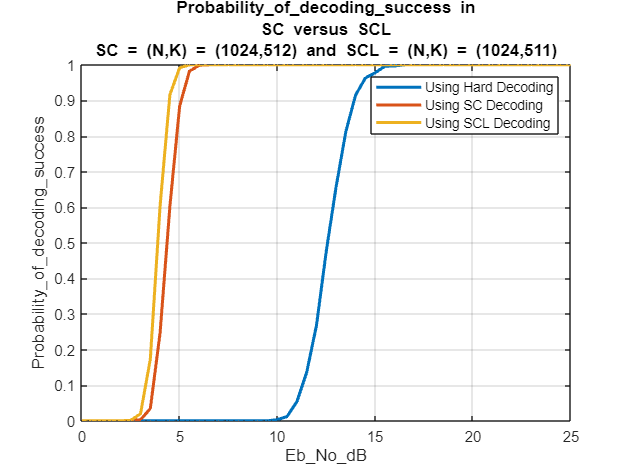

clearvars;
close all;
clc;

tic
load('Reliability_Sequence.mat');
N = 1024;
n = log2(N);

K_Hard = 512;
Rate_hard = K_Hard/N;

K_SC = 512;
Rate_SC = K_SC/N; 

A = 500;
CRC_Length = 11;
CRC_Polynomial = fliplr([1 1 1 0 0 0 1 0 0 0 0 1]);
K_SCL = A + CRC_Length;
Rate_SCL = A/N;

global List_size;
List_size = 4;

Sequence = Reliability_Sequence(Reliability_Sequence <= N);
Frozen_bits_SC = Sequence(1:N-K_SC);
Frozen_bits_SCL = Sequence(1:N-K_SCL);

Nsim = 1000;
Eb_No_Range = 0:0.5:25;

Probability_of_decoding_success_Hard = zeros(1, length(Eb_No_Range));
Bit_Error_Rate_Hard = zeros(1, length(Eb_No_Range));
Block_Errors_Rate_Hard = zeros(1, length(Eb_No_Range));

Probability_of_decoding_success_SC = zeros(1, length(Eb_No_Range));
Bit_Error_Rate_SC = zeros(1, length(Eb_No_Range));
Block_Errors_Rate_SC = zeros(1, length(Eb_No_Range));

Probability_of_decoding_success_SCL = zeros(1, length(Eb_No_Range));
Bit_Error_Rate_SCL = zeros(1, length(Eb_No_Range));
Block_Errors_Rate_SCL = zeros(1, length(Eb_No_Range));

Iteration_index = 1;
Generator_Matrix = Generator_Matrix_for_n_bits(n);

% Hard Decoding
for Eb_No = Eb_No_Range
    Successful_Decoding = 0;
    Nsim_block_errors = 0; 
    Nsim_bit_errors = 0;

    for block = 1:Nsim
        message_sequence = randi([0 1], 1, K_Hard);
        message = zeros(1, N);
        message(Sequence(N-K_Hard+1:end)) = message_sequence;
        
        code_word = Polar_Encoding(message, Generator_Matrix);
        code_word = BPSK_AWGN_Introduction(code_word, Eb_No, K_Hard, N);
        
        message_cap = Polar_Hard_Decode(code_word, N);
        message_cap = message_cap(Sequence(N-K_Hard+1:end));
   
        Evident_errors = sum(message_sequence ~= message_cap);
        if(Evident_errors == 0)
            Successful_Decoding = Successful_Decoding + 1;
        else
            Nsim_bit_errors = Nsim_bit_errors + Evident_errors;
            Nsim_block_errors = Nsim_block_errors + 1;
        end
    end

    Probability_of_decoding_success_Hard(Iteration_index) = (1/Nsim)*Successful_Decoding;
    Bit_Error_Rate_Hard(Iteration_index) = Nsim_bit_errors/K_Hard/Nsim;
    Block_Errors_Rate_Hard(Iteration_index) = Nsim_block_errors/Nsim;
    Iteration_index = Iteration_index + 1;
end
Iteration_index = 1;

% Simple Successive Cancellation Decoding
for Eb_No = Eb_No_Range
    Successful_Decoding = 0;
    Nsim_block_errors = 0; 
    Nsim_bit_errors = 0;

    for block = 1:Nsim
        message_sequence = randi([0 1], 1, K_SC);
        message = zeros(1, N);
        message(Sequence(N-K_SC+1:end)) = message_sequence;
        
        code_word = Polar_Encoding(message, Generator_Matrix);
        code_word = BPSK_AWGN_Introduction(code_word, Eb_No, K_SC, N);
        
        global L_SC;
        global ucap_SC;
        global nodes_SC;
        
        L_SC = zeros(n+1,N);
        L_SC(1,:) = code_word;
        ucap_SC = zeros(n+1,N);
        nodes_SC = zeros(n+1,1);
        
        Initial_Depth = 1;
        Polar_Decode_SC(code_word, Initial_Depth, n, Frozen_bits_SC);
        message_cap = ucap_SC(n+1, Sequence(N-K_SC+1:end));
   
        Evident_errors = sum(message_sequence ~= message_cap);
        if(Evident_errors == 0)
            Successful_Decoding = Successful_Decoding + 1;
        else
            Nsim_bit_errors = Nsim_bit_errors + Evident_errors;
            Nsim_block_errors = Nsim_block_errors + 1;
        end
    end

    Probability_of_decoding_success_SC(Iteration_index) = (1/Nsim)*Successful_Decoding;
    Bit_Error_Rate_SC(Iteration_index) = Nsim_bit_errors/K_SC/Nsim;
    Block_Errors_Rate_SC(Iteration_index) = Nsim_block_errors/Nsim;
    Iteration_index = Iteration_index + 1;
end
Iteration_index = 1;

% Successive List Decoding 
for Eb_No = Eb_No_Range
    Successful_Decoding = 0;
    Nsim_block_errors = 0; 
    Nsim_bit_errors = 0;

    for block = 1:Nsim
        message_sequence = randi([0 1], 1, A);
        [quotient, remainder] = gfdeconv([zeros(1, CRC_Length) fliplr(message_sequence)], CRC_Polynomial);
        CRC_padded_message = [message_sequence fliplr([remainder zeros(1, CRC_Length - length(remainder))])];
        message = zeros(1, N);
        message(Sequence(N-K_SCL+1:end)) = CRC_padded_message;
        
        code_word = Polar_Encoding(message, Generator_Matrix);
        code_word = BPSK_AWGN_Introduction(code_word, Eb_No, A, N);

        global L;
        global ucap;
        global Path_matrix;
        global Node_states;

        L = zeros(List_size, n+1, N);
        L(:,1,:) = repmat(code_word, List_size, 1, 1);
        ucap = zeros(List_size, n+1, N);
        Node_states = zeros(1, 2*N-1);
        Path_matrix = Inf*ones(List_size, 1);
        Path_matrix(1) = 0;
        
        Initial_Depth = 0;
        Initial_Node = 0;
        Polar_Decode_SCL(Initial_Depth, Initial_Node, n, Frozen_bits_SCL);
        message_cap_temp = squeeze(ucap(:,n+1, Sequence(N-K_SCL+1:end)));
        selected_code_word = 1;
        for count = 1:List_size
             [new_quotient, new_remainder] = gfdeconv(fliplr(message_cap_temp(count,:)), CRC_Polynomial);
             if (isequal(new_remainder, 0))
                 selected_code_word = count;
                 break;
             end
        end
        message_cap = message_cap_temp(selected_code_word, 1:A);
 
        Evident_errors = sum(message_sequence ~= message_cap);
        if(Evident_errors == 0)
            Successful_Decoding = Successful_Decoding + 1;
        else
            Nsim_bit_errors = Nsim_bit_errors + Evident_errors;
            Nsim_block_errors = Nsim_block_errors + 1;
        end
    end

    Probability_of_decoding_success_SCL(Iteration_index) = (1/Nsim)*Successful_Decoding;
    Bit_Error_Rate_SCL(Iteration_index) = Nsim_bit_errors/A/Nsim;
    Block_Errors_Rate_SCL(Iteration_index) = Nsim_block_errors/Nsim;
    Iteration_index = Iteration_index + 1;
end

plot(Eb_No_Range, Probability_of_decoding_success_Hard, Eb_No_Range, Probability_of_decoding_success_SC, Eb_No_Range, Probability_of_decoding_success_SCL, 'LineWidth', 2);
title("Probability\_of\_decoding\_success in" + newline + "SC versus SCL" + newline + "SC = (N,K) = (" + num2str(N) + "," + num2str(K_SC) + ") and " + "SCL = (N,K) = (" + num2str(N) + "," + num2str(K_SCL) + ")");
xlabel('Eb\_No\_dB');
ylabel('Probability\_of\_decoding\_success');
legend('Using Hard Decoding', 'Using SC Decoding', 'Using SCL Decoding');
grid on;

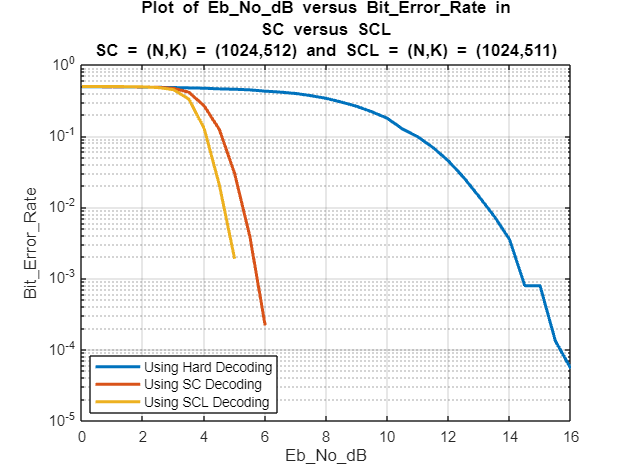

semilogy(Eb_No_Range, Bit_Error_Rate_Hard, Eb_No_Range, Bit_Error_Rate_SC, Eb_No_Range, Bit_Error_Rate_SCL, 'LineWidth', 2);
title("Plot of Eb\_No\_dB versus Bit\_Error\_Rate in" + newline + "SC versus SCL" + newline + "SC = (N,K) = (" + num2str(N) + "," + num2str(K_SC) + ") and " + "SCL = (N,K) = (" + num2str(N) + "," + num2str(K_SCL) + ")");
xlabel('Eb\_No\_dB');
ylabel('Bit\_Error\_Rate');
legend('Using Hard Decoding', 'Using SC Decoding', 'Using SCL Decoding');
grid on;

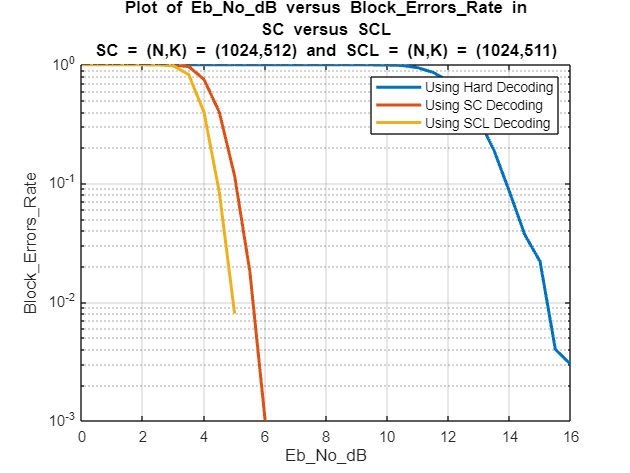

semilogy(Eb_No_Range, Block_Errors_Rate_Hard, Eb_No_Range, Block_Errors_Rate_SC, Eb_No_Range, Block_Errors_Rate_SCL, 'LineWidth', 2);
title("Plot of Eb\_No\_dB versus Block\_Errors\_Rate in" + newline + "SC versus SCL" + newline + "SC = (N,K) = (" + num2str(N) + "," + num2str(K_SC) + ") and " + "SCL = (N,K) = (" + num2str(N) + "," + num2str(K_SCL) + ")");
xlabel('Eb\_No\_dB');
ylabel('Block\_Errors\_Rate');
legend('Using Hard Decoding', 'Using SC Decoding', 'Using SCL Decoding');
grid on;

toc

Elapsed time is 10054.322980 seconds.


function Generator_Matrix = Generator_Matrix_for_n_bits(bit_length)
    Generator_Matrix = [1 0; 1 1];
    A = Generator_Matrix;
    B = Generator_Matrix;
    for count = 1:bit_length-1
       A = kron(A, B);
    end
    Generator_Matrix = A;
end

function code_word = Polar_Encoding(message, Generator_Matrix)
    code_word = mod(message * Generator_Matrix, 2);
end

function [y, pos] = mink(x, k)
    [xs, I] = sort(x);
    y = xs(1:k);
    pos = I(1:k);
end

function code_word = BPSK_AWGN_Introduction(code_word, Eb_No_dB, K, N)
    BPSK_modulated_code_word = 1 - 2*code_word;
    Eb_No = 10^(Eb_No_dB/10);
    Es_No = (K/N) * (Eb_No);
    sigma = sqrt(1 / Es_No);
    AWGN = sigma.*randn(1, N);
    
    code_word = BPSK_modulated_code_word + AWGN;
end

function Message_cap = Polar_Hard_Decode(received_bits, N)
    Message_cap = zeros(1, N);
    message_index = 1;
    code_word_cap = (received_bits < 0);
    queue = {};
    queue{end+1} = code_word_cap;
    
    while(~isempty(queue))
        element_1 = queue{1};
        queue(1) = [];

        if(length(element_1) == 1)
            Message_cap(message_index) = element_1;
            message_index = message_index + 1;
            continue;
        end

        size = length(element_1);
        a = element_1(1:size/2);
        b = element_1(size/2+1:end);

        left = xor(a, b);
        right = b;
        queue{end+1} = left;
        queue{end+1} = right;
    end
end

function Polar_Decode_SC(received_bits,depth,n,Frozen_bits)
    global L_SC;
    global ucap_SC;
    global nodes_SC;

    f=@(r1,r2) sign(r1).*sign(r2).*min(abs(r1),abs(r2));
    g=@(r1,r2,c)r2+(1-2*c).*r1;
    node = nodes_SC(depth);

    if depth == n+1
        nodes_SC(depth) = nodes_SC(depth) + 1;
        if any(Frozen_bits == (node+1)) 
            ucap_SC(n+1,node+1) = 0; 
        else 
            if L_SC(n+1,node+1) >= 0 
                ucap_SC(n+1,node+1) = 0; 
            else 
                ucap_SC(n+1,node+1) = 1; 
            end 
       end 
       return;
    end

    temp=2^(n-depth+1);
    a = received_bits(1:temp/2);
    b = received_bits(temp/2+1:end);
    L_SC(depth+1,temp/2*node+1:temp/2*(node+1)) = f(a,b);
    new_set = f(a,b);
    nodes_SC(depth) = nodes_SC(depth) + 1;
    Polar_Decode_SC(new_set, depth+1, n, Frozen_bits);

    ucap_left = ucap_SC(depth+1, temp/2*node+1:temp/2*(node+1));
    node = nodes_SC(depth);
    L_SC(depth+1, temp/2*node+1:temp/2*(node+1)) = g(a,b,ucap_left);
    nodes_SC(depth) = nodes_SC(depth) + 1;
    new_set_2 = g(a,b,ucap_left);
    Polar_Decode_SC(new_set_2,depth+1,n,Frozen_bits);

    ucap_right = ucap_SC(depth+1,temp/2*node+1:temp/2*(node+1));
    ucap_left = ucap_SC(depth+1,(((temp/2)*node)-(temp/2)+1):temp/2*(node));
    ucap_SC(depth, (((temp/2)*node)-(temp/2)+1):temp/2*(node+1)) = [mod(ucap_left + ucap_right, 2) ucap_right];
end

function Polar_Decode_SCL(Depth, Node, n, Frozen_bits)
    global L;
    global ucap;
    global Path_matrix;
    global List_size;
    global Node_states;

    f = @(r1,r2) (1-2*(r1<0)).*(1-2*(r2<0)).*min(abs(r1),abs(r2));
    g = @(r1,r2,c) r2+(1-2*c).*r1; 

    Node_Position = (2^Depth-1) + Node + 1;

    if Depth == n
       Node_states(Node_Position) = 3;
       Decision_matrix = squeeze(L(:, Depth+1, Node+1));   
       if any(Frozen_bits == (Node+1)) 
            ucap(:, Depth+1, Node+1) = 0; 
            Path_matrix = Path_matrix + abs(Decision_matrix).*(Decision_matrix < 0);
       else 
            Decisions = Decision_matrix < 0;
            Path_matrix_2 = [Path_matrix; Path_matrix + abs(Decision_matrix)];
            [Path_matrix, Position] = mink(Path_matrix_2, List_size);
            Surviving_Position = Position > List_size;
            Position(Surviving_Position) = Position(Surviving_Position) - List_size;
            Decisions = Decisions(Position);
            Decisions(Surviving_Position) = 1 - Decisions(Surviving_Position);
            L = L(Position, :, :);
            ucap = ucap(Position, :, :);
            ucap(:, Depth+1, Node+1) = Decisions;
       end 
       return;
    end

    temp = 2^(n-Depth);
    received_bits = squeeze(L(:, Depth+1, temp*Node+1:temp*(Node+1)));   
    if(Node_states(Node_Position) == 0)
        Node_states(Node_Position) = 1;
        a = received_bits(:, 1:temp/2);
        b = received_bits(:, temp/2+1:end);
        L(:, Depth+2, (temp/2)*(2*Node)+1:(temp/2)*((2*Node)+1)) = f(a,b);
        Polar_Decode_SCL(Depth+1, 2*Node, n, Frozen_bits);
    end

    received_bits = squeeze(L(:, Depth+1, temp*Node+1:temp*(Node+1))); 
    if(Node_states(Node_Position) == 1)
        Node_states(Node_Position) = 2;
        a = received_bits(:, 1:temp/2);
        b = received_bits(:, temp/2+1:end);
        Left_ucap = squeeze(ucap(:, Depth+2, (temp/2)*(2*Node)+1:(temp/2)*((2*Node)+1)));
        L(:, Depth+2, (temp/2)*(2*Node+1)+1:(temp/2)*((2*Node+1)+1)) = g(a, b, Left_ucap);
        Polar_Decode_SCL(Depth+1, 2*Node+1, n, Frozen_bits);
    end
    
    if(Node_states(Node_Position) == 2)
        Node_states(Node_Position) = 3;
        Left_ucap = squeeze(ucap(:, Depth+2, (temp/2)*(2*Node)+1:(temp/2)*((2*Node)+1))); 
        Right_ucap = squeeze(ucap(:, Depth+2, (temp/2)*(2*Node+1)+1:(temp/2)*((2*Node+1)+1)));
        ucap(:, Depth+1, temp*Node+1:temp*(Node+1)) = [mod(Left_ucap + Right_ucap, 2) Right_ucap]; 
    end
end